filelist = dir('C:\Users\arkar\Downloads\ENN543_Assignment2_Data\Q2\UTKFace\UTKFace\*.jpg');
targetsize = 64;
images = zeros(targetsize,targetsize,1,length(filelist));
ages = zeros(length(filelist),1);
gender = zeros(length(filelist),1);
race = zeros(length(filelist),1);

for i=1:length(filelist)
    imgs = imresize(rgb2gray(imread(strcat(filelist(i).folder, "/", filelist(i).name))), [targetsize, targetsize]);
    images(:,:,:,i) = imgs;
    values = split(filelist(i).name, '_');
    ages(i) = double(string(values(1)));
    gender(i) = double(string(values(2)));
    race(i) = double(string(values(3)));
end

rng(4)
idx=randsample(1:length(ages),round(length(ages)*0.8),'false');
ages_train=ages(idx,:);
ages_test=ages;
ages_test(idx,:)=[];

data_to_train=reshape(images, [64*64, length(images)])';

faces_train=data_to_train(idx,:);
faces_test=data_to_train;
faces_test(idx,:)=[];

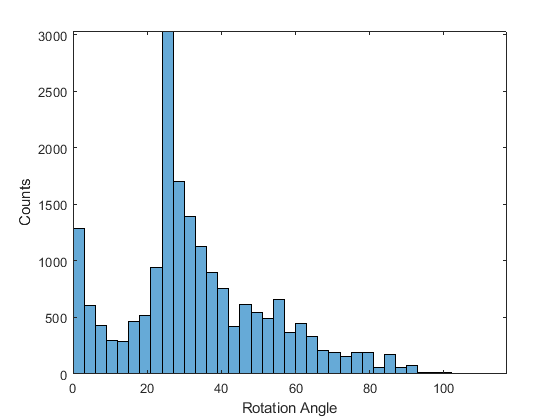

figure 
histogram(ages_train)
axis tight
ylabel('Counts')
xlabel('Rotation Angle')

layers =[
    imageInputLayer([64 64 1])
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    averagePooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    averagePooling2dLayer(2,'Stride',2)
  
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
  dropoutLayer(0.2)
  fullyConnectedLayer(1)
  regressionLayer]

layers =   18x1 Layer array with layers:

     1   ''   Image Input           64x64x1 images with 'zerocenter' normalization
     2   ''   Convolution           8 3x3 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization   Batch normalization
     4   ''   ReLU                  ReLU
     5   ''   Average Pooling       2x2 average pooling with stride [2  2] and padding [0  0  0  0]
     6   ''   Convolution           16 3x3 convolutions with stride [1  1] and padding 'same'
     7   ''   Batch Normalization   Batch normalization
     8   ''   ReLU                  ReLU
     9   ''   Average Pooling       2x2 average pooling with stride [2  2] and padding [0  0  0  0]
    10   ''   Convolution           32 3x3 convolutions with stride [1  1] and padding 'same'
    11   ''   Batch Normalization   Batch normalization
    12   ''   ReLU                  ReLU
    13   ''   Convolution 

    
miniBatchSize  = 128;
validationFrequency = floor(numel(ages_train)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',1e-3, ...
    'LearnRateSchedule','piecewise', ...
    'Shuffle','every-epoch', ...
    'ValidationData',{faces_test,ages_test}, ...
    'ValidationFrequency',validationFrequency, ...
    'Plots','training-progress', ...
    'Verbose',false);
net = trainNetwork(faces_train,ages_train,layers,options);

Error using trainNetwork (line 165)
Number of observations in X and Y disagree.